Detailed explanation of this and related functions: **select_Xp.m** and **mtmetrop.m**

This function computes multi-try proposals using parallel direction (= differential evolution I) and snooker updates using existing chain states. In the multi-try variant of the Metropolis algorithm, we must account for the non-symmetry of the snooker proposals. Let's look at the acceptance probability of a snooker proposal. The screenshot below is copied from Ter Braak & Vrugt (2008), Stat Comput (2008) 18: 435–446, [https://doi.org/10.1007/s11222-008-9104-9](https://doi.org/10.1007/s11222-008-9104-9)

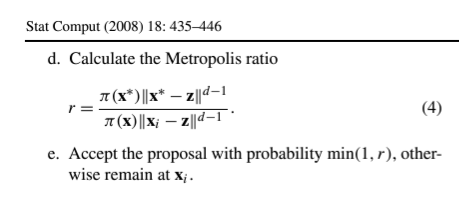

Now, let's go back to the **general definition** of the **acceptance probability** in the Metropolis-Hastings algorithm. I copy below from Wikipedia: [https://en.wikipedia.org/wiki/Metropolis%E2%80%93Hastings_algorithm](https://en.wikipedia.org/wiki/Metropolis%E2%80%93Hastings_algorithm)

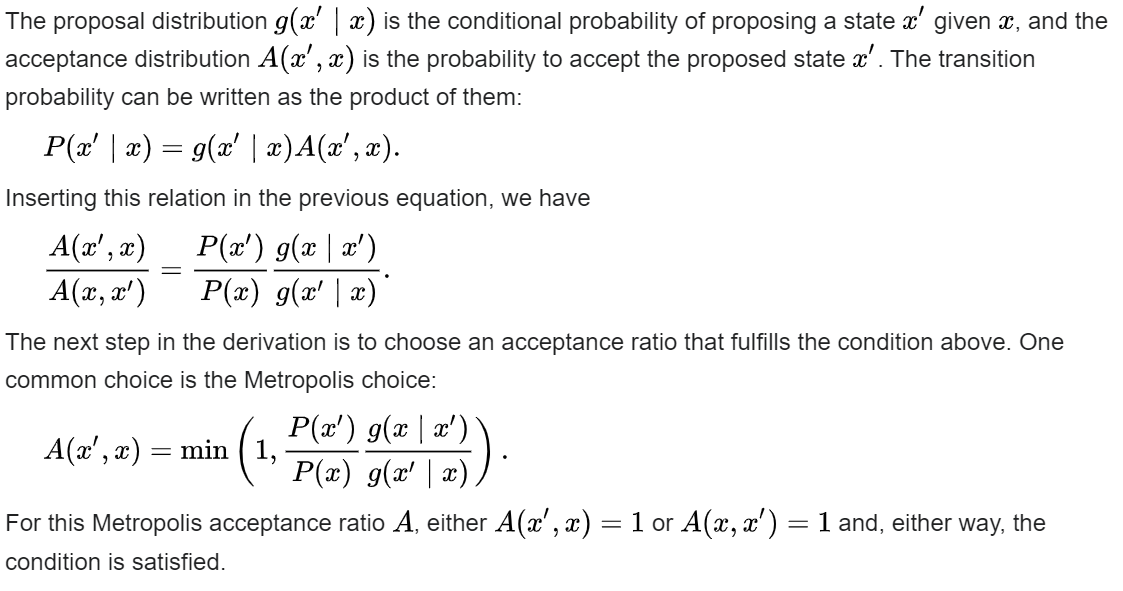

Thus, the **acceptance probability** of a snooker proposal in Ter Braak & Vrugt can be written as


$$r = \frac{\pi(\mathbf{x}_\text{p})q(\mathbf{x}_{i}|\mathbf{x}_\text{p})}{\pi(\mathbf{x}_{i})q(\mathbf{x}_\text{p}|\mathbf{x}_{i})} = \frac{\pi(\mathbf{x}_\text{p})\|\mathbf{x}_\text{p} - \mathbf{x}_{i}\|^{d-1}}{\pi(\mathbf{x}_{i})\|\mathbf{x}_{i} - \mathbf{z}\|^{d-1}}$$


where $\mathbf{x}_\text{p}$ is the proposed point, $\mathbf{x}_{i}$ is the current chain state and $\mathbf{z}$ is a sample from the external archive. The different vector, $\mathbf{x}_{i} - \mathbf{z}$ serves as projection vector. From this exercise we conclude that the transition density, $q(\mathbf{x}_\text{p}|\mathbf{x}_{i}) = \|\mathbf{x}_{i} - \mathbf{z}\|^{d-1}$. **This is important**, as it will come back later. 

Now, how should we deal with **multiple proposals** at once? I copy below the recipe of Luca Martino, "*A Review of Multiple Try MCMC algorithms for Signal Processing*", [https://arxiv.org/pdf/1801.09065](https://arxiv.org/pdf/1801.09065)

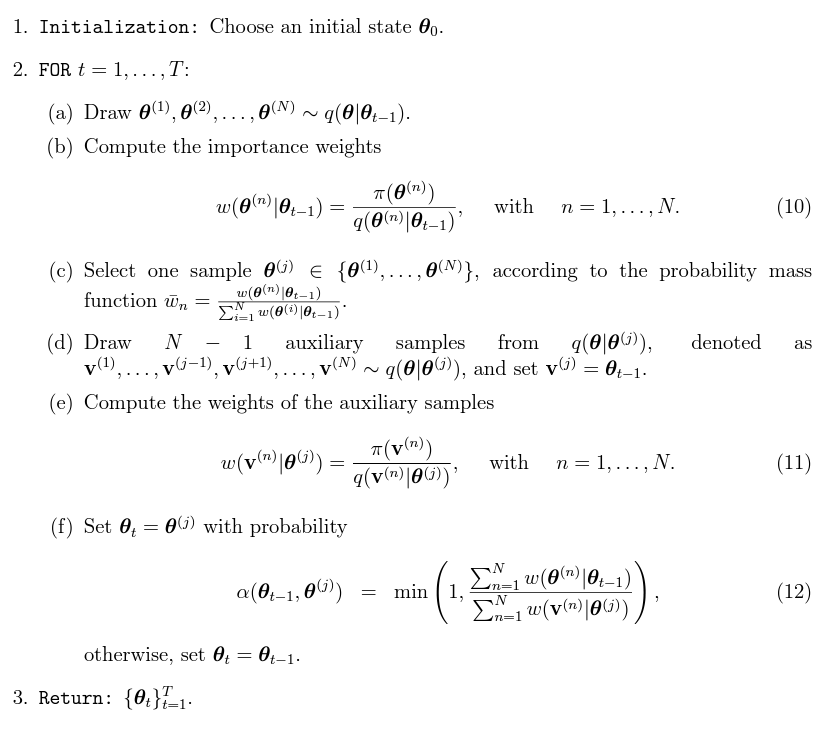

Thus, in step (a) we sample *N* (= $\texttt{mt}$ in MATLAB code) different candidate points. This equals Step 1 in the code below. For each candidate point, we must know the denominator in Equation 10. This denominator equals $q(\mathbf{x}_\text{p}|\mathbf{x}_{i}) $in our snooker update. In logarithmic form, Equation 10 equals


$$\log(w(\mathbf{x}_\text{p}\vert \mathbf{x}_{i})) = \log(\pi(\mathbf{x}_\text{p})) - \log(q(\mathbf{x}_\text{p}\vert \mathbf{x}_{i}))$$
 

For the snooker update, we determined above that $q(\mathbf{x}_\text{p}|\mathbf{x}_{i}) = \|\mathbf{x}_{i} - \mathbf{z}\|^{d-1}$ and, thus, the expression for the importance weight becomes


$$\log(w(\mathbf{x}_\text{p}\vert \mathbf{x}_{i})) = \log(\pi(\mathbf{x}_\text{p})) - \log(\|\mathbf{x}_{i} - \mathbf{z}\|^{d-1}) = \log(\pi(\mathbf{x}_\text{p})) -  (d-1)\log(\|\mathbf{x}_{i} - \mathbf{z}\|)$$


In the MATLAB code below, I called the last term on the right-hand side $\texttt{log\_alfa\_sn\_X}$. I ignore the minus in front for now. Then $\log(\pi(\mathbf{x}_\text{p}))$ is evaluated by another function in **MTDREAM_ZS.m **and the sum of the two, $\log(w(\mathbf{x}_\text{p}\vert \mathbf{x}_{i}))$ is then computed in the function **Select_Xp.m** and used to determine the preferrred candidate point in each chain. This is referred to as $\theta^{(j)}$ in the recipe of Martino. The Select_Xp.m function returns the logarithmic importance weights, $\log(w(\mathbf{x}_\text{p}\vert \mathbf{x}_{i}))$ so as to avoid issues with **numerical underflow** in the computation of the Metropolis acceptance probability in Equation 12.    

For the auxiliary (reference) points (= Step 2 in MATLAB code), we use the same jump method (DE or snooker), jumprate (gamma) and external archive $\texttt{Z}$ of past samples. As the $\texttt{X}$ samples that enter the function header are now the preferred candidate points, $\theta^{(j)}$, called $\mathbf{x}_\text{p}$ above, the same line that first computed $\texttt{log\_alfa\_sn\_X}$ now equals the logarithmic value of the denominator of Equation 11 of Martino, $q(\mathbf{x}_\text{r}|\mathbf{x}_\text{p}) = \|\mathbf{x}_\text{p} - \mathbf{z}\|^{d-1}$. Then, in **MTDREAM_ZS.m **the prior and log-likelihood of each $\mathbf{x}_\text{r}$ is determined, and this ultimately leads to 


$$\log(w(\mathbf{x}_\text{r}\vert \mathbf{x}_\text{p})) = \log(\pi(\mathbf{x}_\text{r})) - \log(q(\mathbf{x}_\text{r}\vert \mathbf{x}_\text{p}))$$


In the function **mtmetrop.m** the $\log(w(\mathbf{x}_\text{p}\vert \mathbf{x}_{i}))$ and $\log(w(\mathbf{x}_\text{r}\vert \mathbf{x}_\text{p})) $of the candidate and reference points, respectively, enter, to compute the Metropolis acceptance probability of each preferred candidate point. 

function varargout = Calc_MTproposal(X,CR,DREAMPar,Table_gamma, ...
    Par_info,jump_method,step,gamma,Z)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
%  MM   MM TTTTTTTT    DDDDD   RRRRR   EEEEEE  AA   MM   MM               %
%  MM   MM TTTTTTTT    DDDDDD  RRRRRR  EEEEEE AAAA  MM   MM               %
%  MMM MMM TT TT TT    DD   DD RR  RR  EE    AA  AA MMM MMM               %
%  MMMMMMM    TT    -- DD   DD RR  RR  EEEE  AA  AA MMMMMMM ZZZZZZ SSSSSS %
%  MMM MMM    TT    -- DD   DD RRRRRR  EEEE  AAAAAA MMM MMM    ZZZ SSS    %
%  MM   MM    TT       DD   DD RR  RR  EE    AAAAAA MM   MM   ZZZ  SSSSSS %
%  MM   MM    TT       DDDDDD  RR  RR EEEEEE AA  AA MM   MM ZZZ       SSS %
%  MM   MM    TT       DDDDD   RR  RR EEEEEE AA  AA MM   MM ZZZZZZ SSSSSS %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
% Calculate candidate points using discrete proposal distribution         %
%                                                                         %
% SYNOPSIS:                                                               %
%  [Xp,log_alfa_sn_X,v,Z,CR_mt,gamma] = Calc_MTproposal(X,CR, ...         %
%   DREAMPar,Table_gamma,Par_info,jump_method,step,gamma,Z)               %
% where                                                                   %
%  X           [input] Nxd matrix of current chain states                 %
%  CR          [input] Nx1 vector of crossover values                     %
%  DREAMPar    [input] Structure with algorithmic variables               %
%  Table_gamma [input] Table with optimal DE-MC jumprates                 % 
%  Par_info    [input] Parameter structure: Ranges, initial/prior & bnd   %
%  jump_method [input] Scalar, 1: Parallel direction, 2: snooker updated  %
%  step        [input] Scalar, 1: Candidate points, 2: reference points   %
%  gamma       [input] Nx1 vector of jumprates if step 2                  %
%  Z           [input] archive of external samples if step 2              %
%  X           [outpt] (mtxN)xd matrix of candidate points (step 1)       %
%                      (mtx(N-1))xd matrix of reference points (step 2)   %
%  log_alfa_sn [outpt] (mtxN)x1 vector log snookr trans. density (step 1) %
%                      (mtx(N-1))x1 vector log snkr trans. dnsty (step 2) %
%  v           [outpt] (mtxN)x1 vector with 0/1 proposl in bound (step 1) %
%                      (mtx(N-1))x1 vector 0/1 proposal in bound (step 2) %
%  Z           [outpt] archive of external samples if step 1              %
%  CR_mt       [outpt] mtxN matrix crossover multi-try proposals (step 1) %
%  gamma       [outpt] Nx1 vector jumprates multi-try proposals (step 1)  %
%                                                                         %
%  © Written by Jasper A. Vrugt, Feb 2007                                 %
%  Los Alamos National Laboratory                                         %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %

if nargin < 9, Z = nan(DREAMPar.select,DREAMPar.d,DREAMPar.N); end
if nargin < 8, gamma = []; end
if nargin < 7, step = 1; end

Nmt = DREAMPar.mt * DREAMPar.N;
% Check whether we do proposal or reference step
switch step
    case 1 % PROPOSAL STEP
        MT = DREAMPar.mt;
        switch jump_method
            case 1
                % jumprate of parallel direction proposal
                gamma_de = randsample([0 1],DREAMPar.N,'true', ...
                    [ 1 - DREAMPar.p_unit_gamma DREAMPar.p_unit_gamma ]);
            case 2
                % jumprate of snooker move: U[1,2,2.2]
                gamma_sn = 1.2 + rand(DREAMPar.N,1);
        end
        % Open the external archives with historical chain states
        fid_Z = fopen('Z.bin'); R = nan(DREAMPar.N,DREAMPar.select);
        % Sample from external archive
        for i = 1:DREAMPar.N
            % Without replacement draw rows from Z to create proposals
            R(i,1:DREAMPar.select) = randsample(DREAMPar.m, ...
                DREAMPar.select);
            % Now read from file
            for zz = 1 : DREAMPar.select
                % Open file "Z.bin"
                fseek(fid_Z,(R(i,zz)-1) * (DREAMPar.d + 2) * 8,'bof');
                % Now load row and store in matrix Z
                Z(zz,1:DREAMPar.d,i) = fread(fid_Z,DREAMPar.d,'double')';
            end
        end
        % Close the file
        fclose(fid_Z);
    case 2 % REFERENCE STEP (AUXILIARY PROPOSALS)
        MT = DREAMPar.mt - 1;
        switch jump_method
            case 1
                % Affix jumprate to reference step
                gamma_de = gamma;
            case 2
                % Affix jumprate to reference step
                gamma_sn = gamma;
        end
end
% Copy crossover values MT times ( columnwise - then transpose )
CR_mt = repmat(CR,1,MT)';
% Initialize alfa_sn in log space
log_alfa_sn_X = nan(Nmt,1);
% Initialize return matrix of candidate points
Xp = nan(Nmt,DREAMPar.d);
% Multi-try sampling --> per chain
for i = 1:DREAMPar.N
    % Find the appropriate indices
    id_mt = ((i-1) * DREAMPar.mt + 1) : i * DREAMPar.mt;
    % Set jump vectors of multiple trials equal to zero
    dX = zeros(MT,DREAMPar.d);
    % Calculate the ergodicity perturbation
    eps = DREAMPar.zeta * randn(MT,DREAMPar.d);
    % Randomness each individual chain
    rnd_jump = DREAMPar.lambda * (2 * rand(MT,DREAMPar.d) - 1);
    % Now use parallel direction or snooker move
    switch jump_method
        case 1      % PARALLEL DIRECTION PROPOSAL DISTRIBUTION (DE-I)
            % # chain pairs each individual MT proposal
            delta = randsample( 1 : DREAMPar.delta , MT , 'true' , ...
                (1/DREAMPar.delta) * ones(1,DREAMPar.delta) )';
            % Generate uniform random numbers for each MT proposal
            % to determine which dimension to update
            rnd_cr = rand(MT,DREAMPar.d);
            % Create MT proposals for chain i
            for mt = 1:MT
                % Define r1 and r2
                r1 = DREAMPar.R(1:delta(mt),mt); r2 = DREAMPar.R( ...
                    delta(mt) + 1 : 2*delta(mt),mt);
                % Which gamma to use?
                if ( gamma_de(i) == 1 )
                    % Update all dimensions and set jump rate to one
                    A = 1:DREAMPar.d; gamma_RWM = 1;
                    % Set CR to full jump so pCR adaptation done correctly
                    CR_mt(mt,i) = DREAMPar.nCR;
                else
                    % Derive subset A with dimensions to sample
                    A = find( rnd_cr(mt,1:DREAMPar.d) < ...
                        CR_mt(mt,i)/DREAMPar.nCR);
                    % Make sure that at least one dimension is selected!
                    d_prime = numel(A);
                    if ( d_prime == 0 )
                        a = randperm(DREAMPar.d); A = a(1); d_prime = 1;
                    end
                    % Unpack jump rate
                    gamma_RWM = Table_gamma(d_prime,delta(mt));
                end
                % Calculate jump
                dX(mt,A) = ( 1 + rnd_jump(mt,A) ) .* gamma_RWM .* ...
                    sum( Z(r1,A,i) - Z(r2,A,i) , 1 ) + eps(mt,A);
            end
            % Set snooker correction to zero
            log_alfa_sn_X(id_mt(1:MT),1) = zeros(MT,1);
        case 2      % SNOOKER PROPOSAL DISTRIBUTION
            % Loop over the individual chains
            for mt = 1:MT
                % Sample a, b and c from external archive Z
                a = DREAMPar.R(1,mt); b = DREAMPar.R(2,mt);
                c = DREAMPar.R(3,mt);
                % Define projection vector X(i,:) - Zc
                F = X(i,1:DREAMPar.d) - Z(c,1:DREAMPar.d,i);
                FF = max(F*F',realmin);
                % Orthogonally project of zR1 and zR2 onto F
                zp = F * ( sum((Z(a,1:DREAMPar.d,i) - ...
                    Z(b,1:DREAMPar.d,i)) .* F ) / FF );
                % And define the jump
                dX(mt,1:DREAMPar.d) = (1 + rnd_jump(mt,1:DREAMPar.d)).* ...
                    gamma_sn(i) .* zp + eps(mt,1:DREAMPar.d);
                % Update CR because we only consider full dimensional updte
                CR_mt(mt,i) = DREAMPar.nCR;
                % JAV: 8/14/2024 - theory included in LiveScript function
                log_alfa_sn_X(id_mt(mt),1) = (DREAMPar.d - 1) * ...
                    norm(X(i,1:DREAMPar.d) - Z(c,1:DREAMPar.d,i),2);
                % JAV: May 2018 --> Page 5 - Ter Braak and Vrugt, 2008 -->
                % P_Xp_to_X = norm( X(i,1:DREAMPar.d) + ...
                %     dX(mt,1:DREAMPar.d) - Z(c,1:DREAMPar.d,i),2); %+realmin
                % Now calculate snooker correction (in log space)
                % log_alfa_sn_X(id_mt(mt),1) = (DREAMPar.d - 1) * ...
                %     log(P_Xp_to_X);
                % This was also used in previous verion of code
                %   --> verified and found correct
            end
    end
    % Store multiple try candidate points of chain i
    Xp(id_mt(1:MT),1:DREAMPar.d) = repmat(X(i,1:DREAMPar.d),MT,1) + dX;
end
% Boundary handling ('bound'/'reflect'/'fold'/'reject')
if isfield(Par_info,'boundhandling')
    [Xp,v] = Boundary_handling(Xp,Par_info);
else
    switch step
        case 1
            % Define violation vector: logical 0) in bound; 1) out of bound
            v = zeros(Nmt,1) > 1;
        case 2
            % Define violation vector: logical 0) in bound; 1) out of bound
            v = zeros(Nmt - DREAMPar.N,1) > 1;
    end
end

switch jump_method
    case 1
        varargout = {Xp log_alfa_sn_X v Z CR_mt gamma_de};
    case 2
        varargout = {Xp log_alfa_sn_X v Z CR_mt gamma_sn};
end

end

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><>
% OLD: THEORY AS SNOOKER PROPOSAL IS NOT SYMMETRIC:
% Summary: We create X_p from X -- and then X_r from X_p
% w(X_p|X) = pi(X_p)*q(X|X_p) * rho(X,X_p); ( THEORY )
% We set rho(X,X_p) = 1
% (see Line 153 of https://arxiv.org/pdf/1801.09065.pdf)
% --> w(X_p|X) = pi(X_p)*q(X|X_p);
% Then the reference weight:
% w(X_r|X_p) = pi(X_r)*q(X_p|X_r);
% Now, q(X|X_p) -> g(x) on Page 4 of Ter Braak and Vrugt:
% q(X|X_p) = || X_p - Z ||^(d-1)
% Then:
% q(X_p|X_r) = || X_r - Z ||^(d-1)
% Now if we take mu = 1 proposal in chain then X_r = X
% alfa(X --> X_p) = w(X_p|X)/w(X_r|X_p)
%                 = pi(X_p)*q(X|X_p) / pi(X_r)*q(X_p|X_r);
%                 = pi(X_p)*q(X|X_p) / pi(X)*q(X_p|X);
%                 = pi(X_p)/pi(X) * ( || X_p - Z ||^(d-1)
%                       / || X - Z ||^(d-1) )
%                 = pi(X_p)/pi(X) * alfa_sn (in DREAM_ZS)
%                 = Equation 4 of Ter Braak & Vrugt (2008)
%
% If we work with log values
% log{alfa(X --> x_p)} = log(pi(X_p)) + log{q(X_p|X)} - ...
%                       ( log(pi(X_r)) + log{q(X_r|X_p)} )
% where
% log{q(X_p|X)} => log_alfa_sn used herein
%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><>
